# read_CastAway.m

**original author: Lewis Drysdale, 2021**

Clear the workspace

clearvars; close('all');


set directory where files are

indir = 'C:\Users\sa01ld\OneDrive - SAMS\Instruments\CastAway\NEXUSS\'

indir = 'C:\Users\sa01ld\OneDrive - SAMS\Instruments\CastAway\NEXUSS\'

Get list of all .csv files

files=dir([indir '*.csv']);

count=0;

for ii=1:numel(files)
    file = fullfile(indir, files(ii).name);
    data=readtable(file);
    if files(ii).bytes>2000 % remove failed casts
        count=count+1;

plot a timeseries of temperature as a profile plot

        x=data.Salinity_PracticalSalinityScale_;
        y=data.Pressure_Decibar_;
        ddtime{count}=[files(ii).name(11:18) ' ' files(ii).name(20:25)];
        figure(1); ax1=subplot(1,2,1);
        plot(x,y,'LineWidth',1.5);
        axis ij; 
        xlabel('Salinity (PSU)'); ylabel('Pressure (db)');
        grid on
        hold on
        legend(ddtime,'Location','southwest');
        
        ax1=subplot(1,2,2);
        scatter(x,y,30,x,'filled');
        colorbar
        axis ij; 
        xlabel('Salinity (PSU)'); ylabel('Pressure (db)');
        grid on
        hold on

        

plot a timeseries of temperature as a profile plot

        x=data.Temperature_Celsius_;
        y=data.Pressure_Decibar_;
        ddtime{count}=[files(ii).name(11:18) ' ' files(ii).name(20:25)];
        figure(2); ax1=subplot(1,2,1);
        plot(x,y,'LineWidth',1.5);
        axis ij; 
        xlabel('Temperature (^o C'); ylabel('Pressure (db)');
        grid on
        hold on
        legend(ddtime,'Location','southwest');
        
        ax1=subplot(1,2,2);
        scatter(x,y,30,x,'filled');
        colorbar
        axis ij; 
        xlabel('Temperature (^o C'); ylabel('Pressure (db)');
        grid on
        hold on
        
    end
   
end

Save the figures

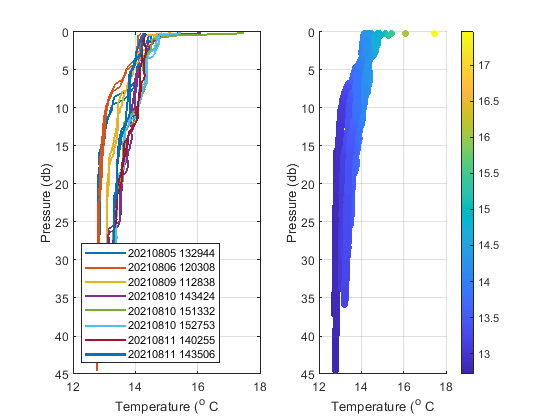

print(figure(2), '-dpng',['figures/temperature-plot']);

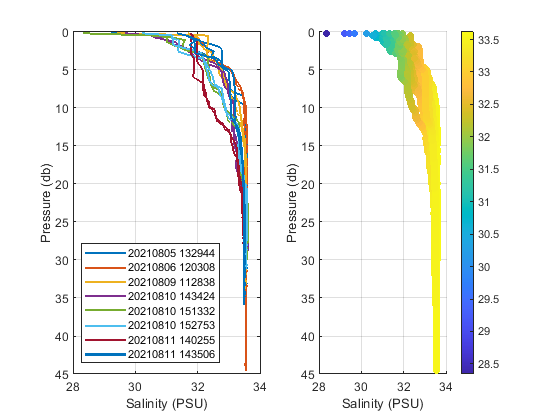

print(figure(1), '-dpng',['figures/salinity-plot']);